# Template of Manipulator Short project: Skull tumor surgery

Authors: **Jose García Torres & Ivan Lopez Buira**

Team:  **G11 - F**

Shared Link with the teacher:  https://drive.mathworks.com/sharing/09b55873-900d-4ef4-a139-6397e28575bd

Remember use the options of serial/link plot: 

'workspace' for centering in the surgery task

'zoom' ...  nice puma ratio aspect

'trail'  .. to see the trajectory

etc..

See all at:

>> help SerialLink/plot

## The Robotic environment (10%)

Think that later on the enviroment will move to any place in a Univers Reference Frame {U}

Use: 'c = uisetcolor' to chose your prefered colors

### Operating table.

 It can be raised, lowered, and tilted in any direction, and an  auxiliary table for the tools. Define: Vertices and Faces and use  'patch'  functions to model it. See help patch to find and example.

**Expected results**

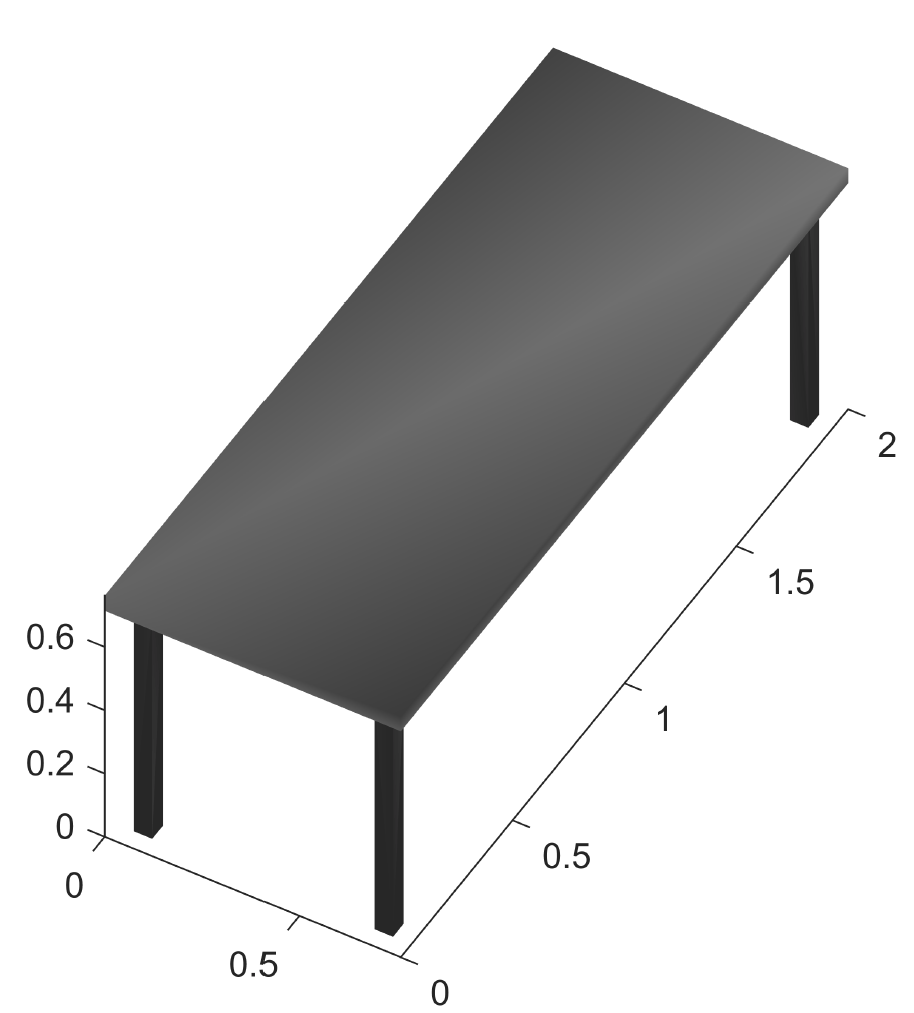

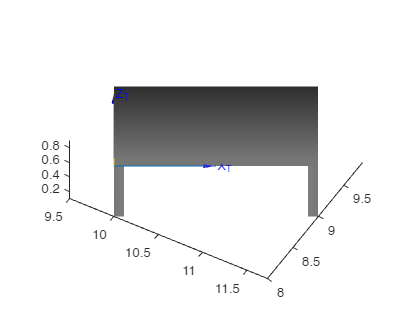

clear
close all
clf

T_M_U = transl(10,8,0.8)*trotz(pi/6); % Reference Frame Taula

v_ini= [0 0 0;1 0 0;1 1 0;0 1 0;0 0 1;1 0 1;1 1 1;0 1 1];
LDH = [2 0 0; 0 1 0; 0 0 0.1];
v = v_ini * LDH;
v = [v ones(size(v,1),1)];
v = (T_M_U * v')';
f = [1 2 6 5;2 3 7 6;3 4 8 7;4 1 5 8;1 2 3 4;5 6 7 8];

mesa = figure;
figure(mesa);
patch('Vertices',v(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
view(30,45)
axis equal

v_pata = v_ini * [0.1 0 0; 0 0.1 0; 0 0 0.7];
v_pata = [v_pata ones(size(v_pata,1),1)];

v_pata1 = (T_M_U * transl(0,0,-0.7) * v_pata')';
v_pata2 = (T_M_U * transl(1.9,0,-0.7) * v_pata')';
v_pata3 = (T_M_U * transl(1.9,0.9,-0.7) * v_pata')';
v_pata4 = (T_M_U * transl(0,0.9,-0.7) * v_pata')';

patch('Vertices',v_pata1(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata2(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata3(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
patch('Vertices',v_pata4(:,(1:3)),'Faces',f,'FaceVertexCData',hsv(6),'FaceColor',[0.5, 0.5 0.5], 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)


camlight('headlight')
material('dull')
view(30,45)
axis equal
hold on

trplot(T_M_U, 'frame', 'T', 'length', 1, 'arrow', 'color', 'b');

### 3D model of a human body 

Situate the human model on the operating table. 

Use: F_V_HumanBody.mat as a model

**Expected results**

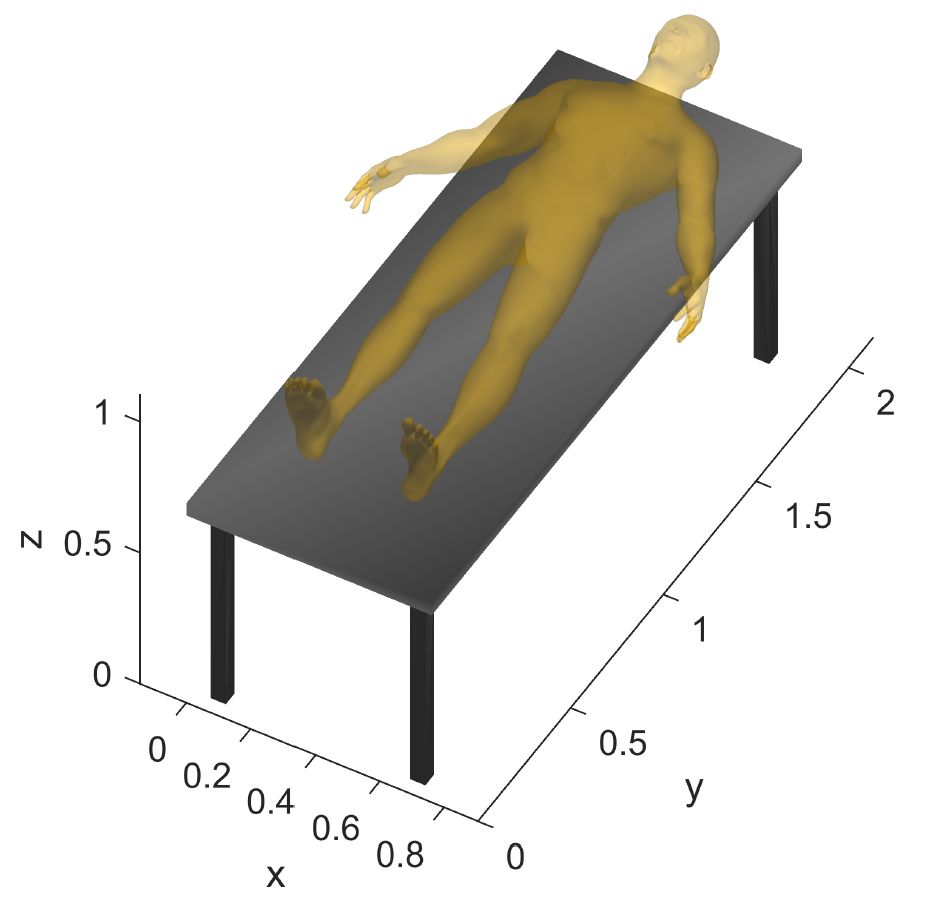

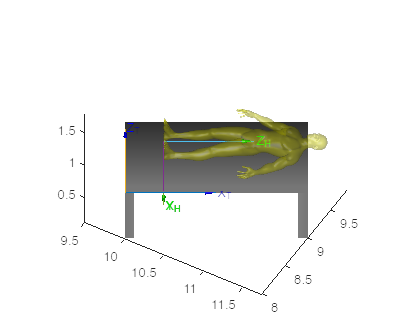

load("F_V_HumanBody.mat")

T_H_M = T_M_U * transl(0.42,0.5,0.3) * troty(pi/2) * trotz(-pi/2); % Reference Frame Humà wrt Taula
v_human = [Vh ones(size(Vh, 1),1)];
v_human = (T_H_M * v_human')';

patch('Vertices',v_human(:,(1:3)),'Faces',Fh,'FaceVertexCData',hsv(6),'FaceColor','y', 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
axis equal

trplot(T_H_M,'frame', 'H', 'length', 1, 'arrow', 'color', 'g');

### Dicom image vs Image Reference frame {I}

Get familiar with Dicom Images and the functionalities of the viewer, Visit: https://www.dicomlibrary.com

Infer the Image Reference Frame {I} and the skull containig box dimensions.

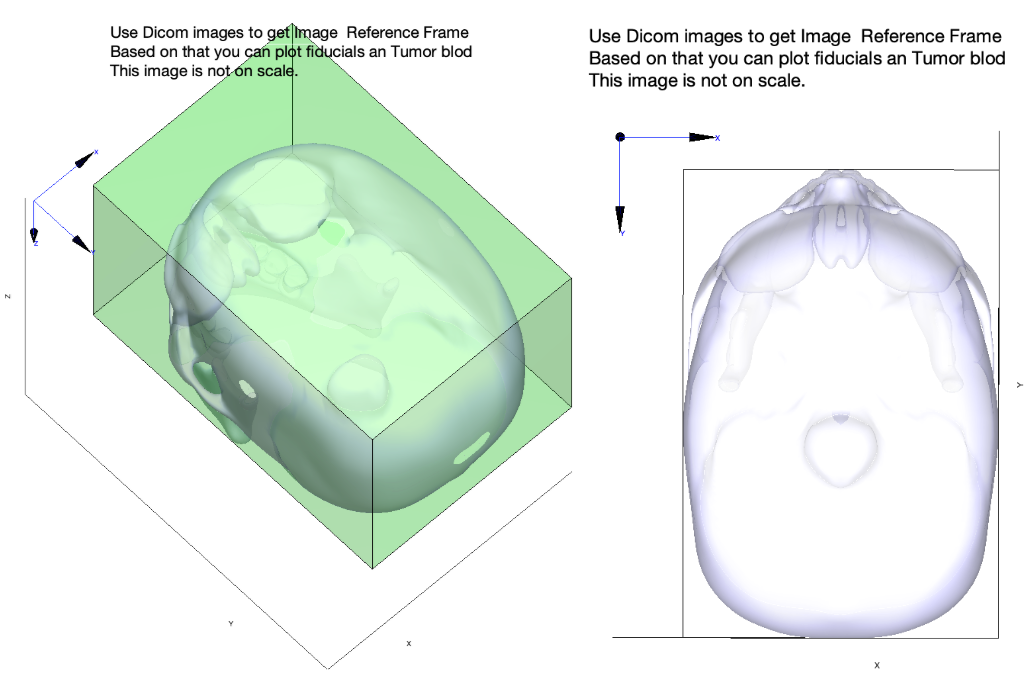

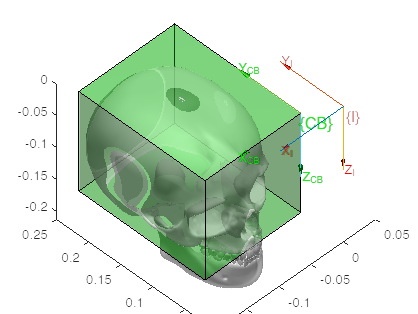

skull = load("F_V_Skull.mat");
skull_vertices = skull.Vs;

T_I = troty(pi); % Reference Frame Imatge

T_CB_I = T_I * transl(0.041,0.026,0); % Reference Frame Capsa Contenidora wrt Imatge

xmaxs = max (skull_vertices(:, 1)); 
xmins = min(skull_vertices(:, 1)); 
ymaxs = max (skull_vertices (:, 2)); 
ymins = min(skull_vertices(:, 2));

xsize = abs(xmaxs - xmins)/2;
ysize = abs(ymaxs - ymins)/2;
zsize = max(skull_vertices( :,3));

T_Skull = T_I * transl(xsize+0.041, ysize+0.026, zsize) * troty(pi); % Ini Skull

skull_vertices = [skull_vertices ones(size(skull_vertices, 1),1)];
skull_vertices = (T_Skull * skull_vertices')';

skull_fig = figure;
figure(skull_fig)


patch('Vertices',skull_vertices(:, 1:3),'Faces',skull.Fs,'FaceVertexCData',hsv(6),'FaceColor','w', 'EdgeColor', 'none', 'FaceAlpha', 0.6, 'FaceLighting', 'gouraud', 'AmbientStrength',0.15)
camlight('headlight')
material('dull')


%Capsa Contenidora Skull

x=0.150;
y=0.198;
z=0.156;
v= [0 0 0;x 0 0;x y 0;0 y 0;0 0 z;x 0 z;x y z;0 y z];

cube_vertices_cb = [v'; ones(1, length(v))];

cube_vertices_cb = (T_CB_I * cube_vertices_cb)';

cube_faces = [ 1 2 6 5; 2 3 7 6; 3 4 8 7; 4 1 5 8; 1 2 3 4; 5 6 7 8];

hold on

patch('Vertices',cube_vertices_cb(:,1:3),'Faces',cube_faces,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.3)
trplot(T_I,'frame', 'I', 'length', 0.1, 'arrow', 'color', 'r')
axis equal
trplot(T_CB_I,'frame', 'CB', 'length', 0.1, 'arrow', 'color', 'g')
axis equal
view(-45,45)

### Fiducials wrt {I}

The Radiology Department before to take a Computer Tomography (CT) of the brain, fix three fiducials in the head of the patient for registering purpose,  visit: [https://en.wikipedia.org/wiki/Fiducial](https://en.wikipedia.org/wiki/Fiducial)

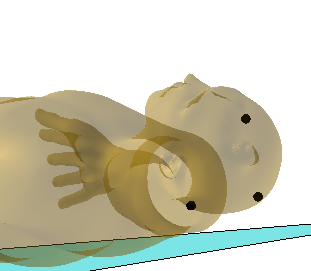

Use the Dicom images to obtain the fiducial coordinates relative to Image Reference Frame {I}.

**Expected results**

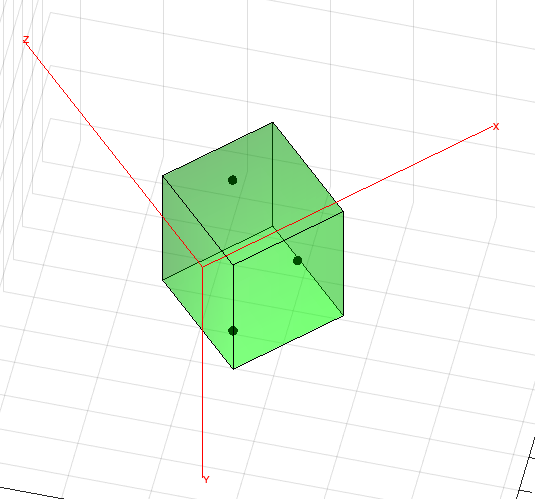

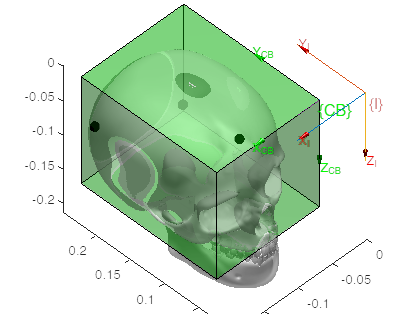

F1_I = [0.06656 0.200 0.112 1]';
F2_I = [0.186 0.209 0.0658 1]';
F3_I = [0.122 0.062 0.0252 1]';

[X,Y,Z] = sphere;

r2 = 0.005;

X3 = X * r2;
Y3 = Y * r2;
Z3 = Z * r2;

F1_U = T_I * F1_I;

hold on

surf(X3+F1_U(1,1),Y3+F1_U(2,1),Z3+F1_U(3,1),'FaceColor',[1 0 0])
axis equal

F2_U = T_I * F2_I;
surf(X3+F2_U(1,1),Y3+F2_U(2,1),Z3+F2_U(3,1),'FaceColor',[1 0 0])
axis equal


F3_U = T_I * F3_I;

surf(X3+F3_U(1,1),Y3+F3_U(2,1),Z3+F3_U(3,1),'FaceColor',[1 0 0])
axis equal

### Tumor points wrt {I}

Use the Dicom images to get the points of the outer perimeter of the tumor relative to Image Reference Frame {I}.

You can simplify the tumor information by defining the center of mass and estimate an equivalent diameter.

**Expected results**

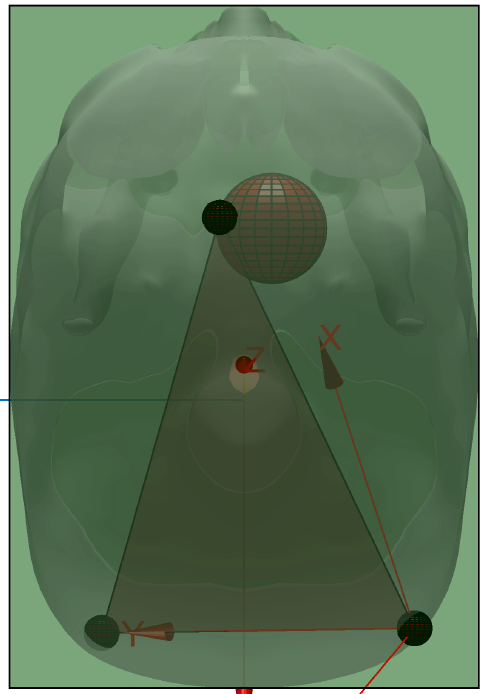

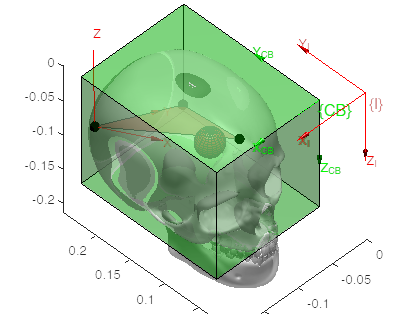

C_T = [0.130 0.097 0.049 1]'; % X Y Z (1)
D_T = 0.033;

[X,Y,Z] = sphere;

r = D_T / 2;

X2 = X * r;
Y2 = Y * r;
Z2 = Z * r;

C_T_U = T_I * C_T;

surf(X2+C_T_U(1,1), Y2+C_T_U(2,1), Z2+C_T_U(3,1),'FaceColor',[1 0 0])
axis equal

triangle = [F1_U(1:3,:), F2_U(1:3,:), F3_U(1:3,:)];
fill3(triangle (1,:), triangle(2, :), triangle(3, :)', 'r', 'FaceAlpha', 0.5)

AB = (triangle(1:3,1) - triangle(1:3,2)) / norm(triangle(1:3,1) - triangle(1:3,2)); % Vector pointing A 
CB = (triangle(1:3,3) - triangle(1:3,2)) / norm(triangle(1:3,2) - triangle(1:3,3)); % Vector pointing C
Z_B = cross(CB, AB) / norm(cross(CB, AB));

orientAB = oa2r(AB, Z_B);
T_F = [orientAB F2_U(1:3); 0 0 0 1];


trplot(T_F, 'length', 0.1, 'arrow', 'color', 'r');
hold off

### Fiducials and Tumor wrt Human Reference Frame

Place fiducial and tumor in the head of the human. 

**Expected results**

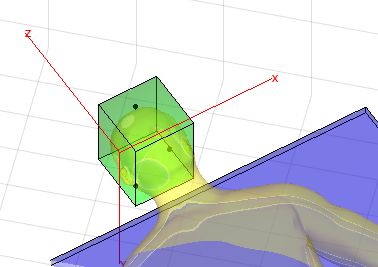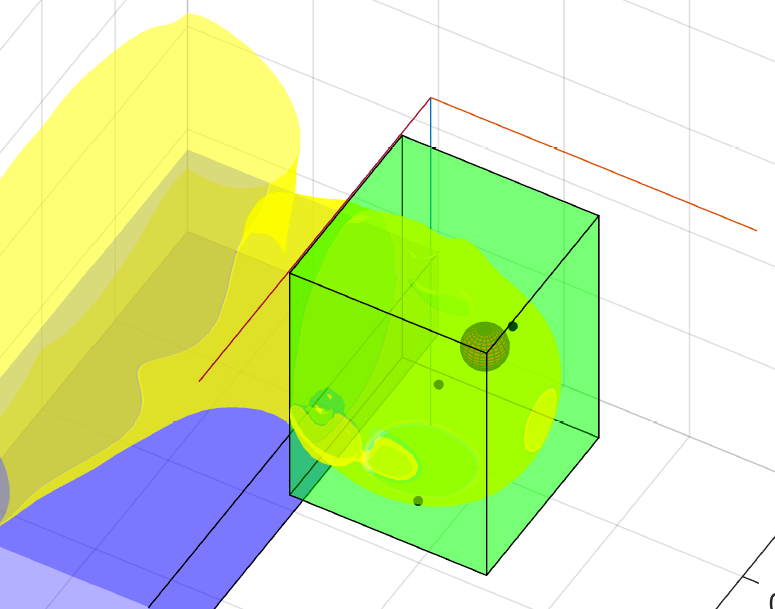

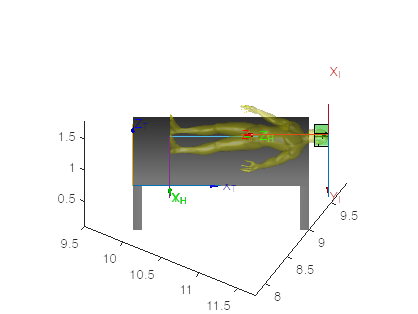

figure(mesa)
hold on

% F1_I = [0.06656 0.200 0.0448 1]';
% F2_I = [0.186 0.209 0.091 1]';
% F3_I = [0.122 0.062 0.1274 1]';

%C_T = [0.130 0.097 0.1078 1]'; % X Y Z (1)

T_I_H = T_H_M * troty(pi) * transl(-(xsize+0.041),-(ysize+0.026),-(1.65+0.15)); % Reference Frame Imagen wrt Humà modificar para que quede como DICOM
T_F_I = T_I_H * transl(-0.015,0.016,0);
T_CB_I = T_I_H * troty(pi);

cube_vertices_cb = (T_CB_I * cube_vertices_cb')';
patch('Vertices',cube_vertices_cb(:, 1:3),'Faces',cube_faces,'FaceVertexCData',hsv(6),'FaceColor','g','FaceAlpha',0.3)

F1_U = T_F_I * F1_I;

surf(X3+F1_U(1,1),Y3+F1_U(2,1),Z3+F1_U(3,1),'FaceColor',[1 0 0])
axis equal

F2_U = T_F_I * F2_I;
surf(X3+F2_U(1,1),Y3+F2_U(2,1),Z3+F2_U(3,1),'FaceColor',[1 0 0])
axis equal

F3_U = T_F_I * F3_I;

surf(X3+F3_U(1,1),Y3+F3_U(2,1),Z3+F3_U(3,1),'FaceColor',[1 0 0])
axis equal

C_T_U = T_F_I * C_T;

surf(X2+C_T_U(1,1), Y2+C_T_U(2,1), Z2+C_T_U(3,1),'FaceColor',[1 0 0])
axis equal

trplot(T_I_H,'frame', 'I', 'length', 1, 'arrow', 'color', 'r')

### Reference Frames

Display all necessary reference frame. Use best scale to see it.

- {U} Univers [0 0 0]

- {R} Robot

- {I} Image

- {Tb} Table_body

- {Tt} Table tool

- {EE} End Efector

- others

- ...